1

Use the method of Separation of Variables to find the solution to the IBVP below. Graph the solution look like for various values of time using Matlab.

PDE                    $u_t =u_{\textrm{xx}}$                    $0<x<1$,    $0<t<\infty$

BCs                     $\left\lbrace \begin{array}{cc}
u\left(0,1\right)=0 & \\
u\left(1,t\right)=0 & 0<t<\infty 
\end{array}\right.$

IC                        $u\left(x,0\right)=\sin \left(2\pi x\right)+\frac{1}{3}\sin \left(4\pi x\right)+\frac{1}{5}\sin \left(6\pi x\right)$                $0\le x\le 1$

Let $u\left(x,t\right)=X\left(x\right)T\left(t\right)$, then the PDE become:


$$\frac{\partial }{\partial t}\left\lbrack X\left(x\right)T\left(t\right)\right\rbrack =\frac{\partial^2 }{\partial x^2 }\left\lbrack X\left(x\right)T\left(t\right)\right\rbrack$$



$$X\left(x\right)T^{\prime } \left(t\right)={X^{\prime } }^{\prime } \left(x\right)T\left(t\right)$$


Then divide both side$X\left(x\right)T\left(t\right)$

 
$$\frac{X\left(x\right)T^{\prime } \left(t\right)}{X\left(x\right)T\left(t\right)}=\frac{{X^{\prime } }^{\prime } \left(x\right)T\left(t\right)}{X\left(x\right)T\left(t\right)}$$



$$\frac{T^{\prime } \left(t\right)}{T\left(t\right)}=\frac{{X^{\prime } }^{\prime } \left(x\right)}{X\left(x\right)}$$


The only result the equation satified is both RHS and LHS equals to constant k.


$$\frac{{X^{\prime } }^{\prime } \left(x\right)}{X\left(x\right)}=\frac{T^{\prime } \left(t\right)}{T\left(t\right)}=k$$


Then


$$\left\lbrace \begin{array}{cc}
\frac{{X^{\prime } }^{\prime } \left(x\right)}{X\left(x\right)}=k & \left(1\right)\\
\frac{T^{\prime } \left(t\right)}{T\left(t\right)}=k & \left(2\right)
\end{array}\right.$$


The solution of (2) is $T\left(t\right)=T\left(0\right)e^{\textrm{kt}}$    (3)

With equation (1)

${X^{\prime } }^{\prime } \left(x\right)-\textrm{kX}\left(x\right)=0$    (4)

Guess with the solution $X\left(x\right)=e^{\textrm{rx}}$

Plug the solution into (4):


$$\begin{array}{l}
{r^2 e^{\textrm{rx}} -\textrm{ke}}^{\textrm{rx}} =0\\
e^{\textrm{rx}} \left(r^2 -k\right)=0
\end{array}$$


so $r^2 -k=0$


$$r^2 =k$$



$$r=\pm \sqrt{k}$$


Then with sign of k, there are three case.

Case 1 $K>0$

let $K=\lambda^2$


$$r=\pm \lambda$$


So the solution is:


$$X\left(x\right)={\textrm{Ae}}^{\lambda x} +{\textrm{Be}}^{-\lambda x}$$


Case 2 $K<0$

let $K=-\lambda^2$


$$\frac{X\left(x\right)}{{X^{\prime } }^{\prime } \left(x\right)}=-\lambda^2$$



$$X\left(x\right)=-\lambda^2 {X^{\prime } }^{\prime } \left(x\right)$$



$$X\left(x\right)=\textrm{Asin}\left(\lambda x\right)+\textrm{Bcos}\left(\lambda x\right)$$


Case 3 $K=0$


$$r=0$$



$$X=1$$


By plug BCs in:

BCs $\left\lbrace \begin{array}{cc}
u\left(0,1\right)=0 & \\
u\left(1,t\right)=0 & 0<t<\infty 
\end{array}\right.$

With Case 1 $K>0$,$K=\lambda^2$


$$u\left(x,t\right)=X\left(x\right)T\left(t\right)=\left({\textrm{Ae}}^{\lambda x} +{\textrm{Be}}^{-\lambda x} \right)T\left(0\right)e^{\lambda t}$$


By plug $u\left(0,1\right)=0$ and $u\left(1,t\right)=0$ in


$$u\left(0,1\right)=\left({\textrm{Ae}}^{\lambda 0} +{\textrm{Be}}^{-\lambda 0} \right)T\left(0\right)e^{\lambda } =\left(A+B\right)T\left(0\right)e^{\lambda } =0$$



$$u\left(1,t\right)=\left({\textrm{Ae}}^{\lambda } +{\textrm{Be}}^{-\lambda } \right)T\left(0\right)e^{\lambda t} =0$$


So $T\left(0\right)=0$

Therefore $\left({\textrm{Ae}}^{\lambda x} +{\textrm{Be}}^{-\lambda x} \right)T\left(0\right)e^{\lambda t}$=0 in all cituation.

So Case 1 $K>0$ is not true

Case 2 $K<0$,$K=-\lambda^2$


$$u\left(x,t\right)=X\left(x\right)T\left(t\right)=\left(\textrm{Asin}\left(\lambda x\right)+\textrm{Bcos}\left(\lambda x\right)\right)T\left(0\right)e^{-\lambda^2 t}$$


By plug $u\left(0,1\right)=0$ and $u\left(1,t\right)=0$ in


$$u\left(0,1\right)=\left(\textrm{Asin}\left(\lambda 0\right)+\textrm{Bcos}\left(\lambda 0\right)\right)T\left(0\right)e^{-\lambda^2 } =\textrm{BT}\left(0\right)e^{-\lambda^2 } =0$$



$$u\left(1,t\right)=\left(\textrm{Asin}\left(\lambda \right)+\textrm{Bcos}\left(\lambda \right)\right)T\left(0\right)e^{-\lambda^2 t} =0$$


Since $T\left(0\right)$ cannot be 0 from Case 1, $\mathrm{B}=0$.


$$u\left(x,t\right)=X\left(x\right)T\left(t\right)=\textrm{Asin}\left(\lambda x\right)T\left(0\right)e^{-\lambda^2 t}$$



$$u\left(1,t\right)=\textrm{Asin}\left(\lambda \right)T\left(0\right)e^{-\lambda^2 t} =0$$



$$\textrm{Asin}\left(\lambda \right)=0$$



$$\lambda =n\pi$$


Case 3 $K=0$


$$u\left(x,t\right)=X\left(x\right)T\left(t\right)=T\left(0\right)e^{\textrm{kt}}$$


$T\left(0\right)=0$ if we plug $u\left(0,1\right)=0$ in.

Therefore Case 2 $K<0$ is true

And $u\left(x,t\right)=X\left(x\right)T\left(t\right)=\sum_{n=1}^{\infty } A_n \sin \left(n\pi x\right)C_n e^{-{\left(n\pi \right)}^2 t}$

let $\overset{~}{A_n =A_n C_n }$


$$u\left(x,t\right)=\sum_{n=1}^{\infty } \overset{~}{A_n } \sin \left(n\pi x\right)e^{-{\left(n\pi \right)}^2 t}$$


Then plug in IC

IC: $u\left(x,0\right)=\sin \left(2\pi x\right)+\frac{1}{3}\sin \left(4\pi x\right)+\frac{1}{5}\sin \left(6\pi x\right)$


$$u\left(x,0\right)=\sum_{n=1}^{\infty } \overset{~}{A_n } \sin \left(n\pi x\right)=\sin \left(2\pi x\right)+\frac{1}{3}\sin \left(4\pi x\right)+\frac{1}{5}\sin \left(6\pi x\right)$$


Multiply $\sin \left(m\pi x\right)$ on both side and then integral, m=1,2,3,...


$$\left\langle \sum_{n=1}^{\infty } \overset{~}{A_n } \sin \left(n\pi x\right),\sin \left(m\pi x\right)\right\rangle =\left\langle \sin \left(2\pi x\right)+\frac{1}{3}\sin \left(4\pi x\right)+\frac{1}{5}\sin \left(6\pi x\right),\sin \left(m\pi x\right)\right\rangle$$



$$\textrm{LHS}=\sum_{n=1}^{\infty } \overset{~}{A_n } \int_0^1 \sin \left(n\pi x\right)\sin \left(m\pi x\right)\textrm{dx}=\left\lbrace \begin{array}{cc}
0 & \textrm{if}\;m\not= n\\
\frac{1}{2} & \textrm{if}\;m=n
\end{array}\right.$$



$$\begin{array}{l}
\textrm{RHS}=\int_0^1 \left(\sin \left(2\pi x\right)+\frac{1}{3}\sin \left(4\pi x\right)+\frac{1}{5}\sin \left(6\pi x\right)\right)\sin \left(m\pi x\right)\textrm{dx}\\
\textrm{RHS}=\int_0^1 \sin \left(2\pi x\right)\sin \left(m\pi x\right)\textrm{dx}+\int_0^1 \frac{1}{3}\sin \left(4\pi x\right)\sin \left(m\pi x\right)\textrm{dx}+\int_0^1 \frac{1}{5}\sin \left(6\pi x\right)\sin \left(m\pi x\right)\textrm{dx}
\end{array}$$



$$\begin{array}{l}
\int_0^1 \sin \left(2\pi x\right)\sin \left(m\pi x\right)\textrm{dx}=\frac{\overset{~}{A_m } }{2}\\
\int_0^1 \frac{1}{3}\sin \left(4\pi x\right)\sin \left(m\pi x\right)\textrm{dx}=\frac{\overset{~}{A_m } }{2}\\
\int_0^1 \frac{1}{5}\sin \left(6\pi x\right)\sin \left(m\pi x\right)\textrm{dx}=\frac{\overset{~}{A_m } }{2}
\end{array}$$


Simplifiy 


$$\begin{array}{l}
\int_0^1 \sin \left(2\pi x\right)\sin \left(2\pi x\right)\textrm{dx}=\frac{\overset{~}{A_2 } }{2}=\frac{1}{2}\\
\int_0^1 \frac{1}{3}\sin \left(4\pi x\right)\sin \left(4\pi x\right)\textrm{dx}=\frac{\overset{~}{A_4 } }{2}=\frac{1}{3}\frac{1}{2}=\frac{1}{6}\\
\int_0^1 \frac{1}{5}\sin \left(6\pi x\right)\sin \left(6\pi x\right)\textrm{dx}=\frac{\overset{~}{A_6 } }{2}=\frac{1}{5}\frac{1}{2}=\frac{1}{10}
\end{array}$$


So $\overset{~}{A_2 } =1$, $\overset{~}{A_4 } =\frac{1}{3}$, $\overset{~}{A_6 } =\frac{1}{5}$, and $\overset{~}{A_n } =0$ with other n

So $u\left(x,t\right)=\sum_{n=1}^{\infty } \overset{~}{A_n } \mathrm{sin}\left(n\pi x\right)e^{-{\left(n\pi \right)}^2 t} =\mathrm{sin}\left(2\pi x\right)e^{-{\left(2\pi \right)}^2 t} +\frac{1}{3}\mathrm{sin}\left(4\pi x\right)e^{-{\left(4\pi \right)}^2 t} +\frac{1}{5}\mathrm{sin}\left(6\pi x\right)e^{-{\left(6\pi \right)}^2 t}$        (5)


$$u_t =-{\left(2\pi \right)}^2 \mathrm{sin}\left(2\pi x\right)e^{-{\left(2\pi \right)}^2 t} -{\left(4\pi \right)}^2 \frac{1}{3}\mathrm{sin}\left(4\pi x\right)e^{-{\left(4\pi \right)}^2 t} -{\left(6\pi \right)}^2 \frac{1}{5}\mathrm{sin}\left(6\pi x\right)e^{-{\left(6\pi \right)}^2 t}$$



$$=-{4\pi }^2 \mathrm{sin}\left(2\pi x\right)e^{-{\left(2\pi \right)}^2 t} -{16\pi }^2 \frac{1}{3}\mathrm{sin}\left(4\pi x\right)e^{-{\left(4\pi \right)}^2 t} -{36\pi }^2 \frac{1}{5}\mathrm{sin}\left(6\pi x\right)e^{-{\left(6\pi \right)}^2 t} \;$$
        

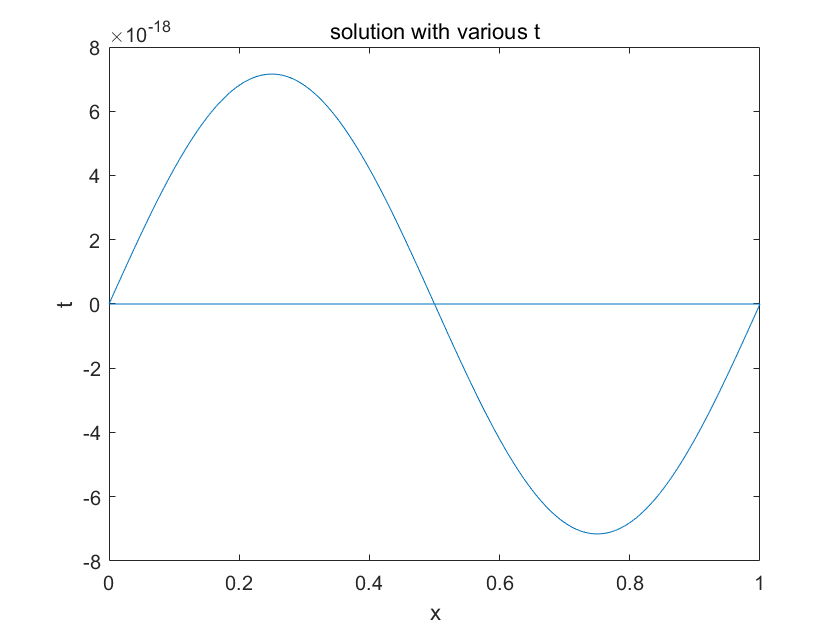

clear
x=linspace(0,1,500);%generate x according to PDE interval (0,1)

for t=1:50
    %loop for t
    plot(x,u(x,t))%plot with each t
    hold on
end

title("solution with various t")
xlabel("x")
ylabel("u(x,t)")

function [uf]=u(x,t)
% equation(5)
    uf=sin(2*pi*x).*exp(-4*pi^2*t) ...
    +1/3*sin(4*pi*x).*exp(-16*pi^2*t) ...
    +1/5*sin(6*pi*x).*exp(-36*pi^2*t);
end